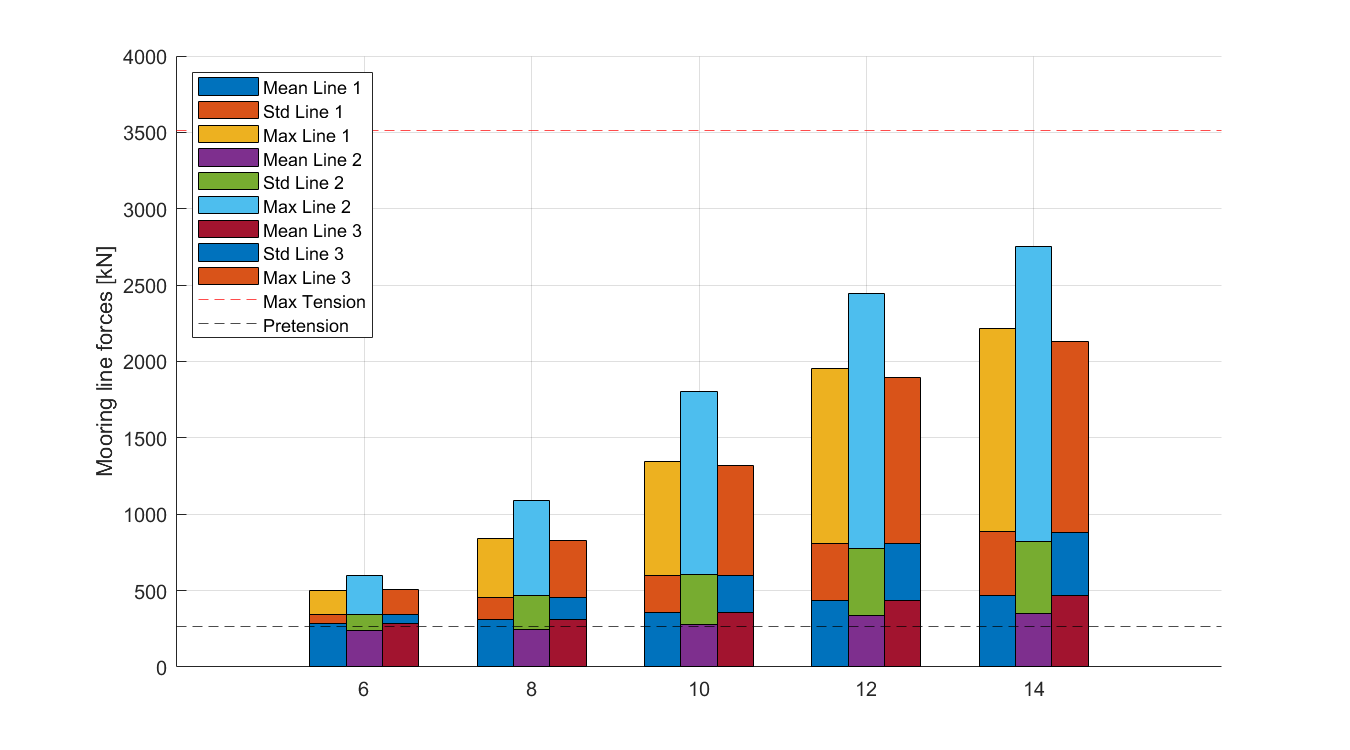

% Define the Excel file name
filename = 'MooringForces.xlsx';

% Define the sheet names
sheetNames = {'6', '8', '10', '12', '14'};

% Initialize arrays to store the calculated values
maxValues = zeros(3, length(sheetNames));
meanValues = zeros(3, length(sheetNames));
stdValues = zeros(3, length(sheetNames));

% Loop through each sheet
for sheetIdx = 1:length(sheetNames)
    % Read the sheet
    sheetName = sheetNames{sheetIdx};
    data = readmatrix(filename, 'Sheet', sheetName);

    % Remove the first 1200 rows
    data = data(1201:end, :);

    % Extract line forces for each line and simulation
    for lineIdx = 1:3
        % Extract the line forces for the current line
        lineForces = data(:, (lineIdx-1)*6 + 1 : lineIdx*6);

        % Calculate max, mean, and std of each column
        colMax = max(lineForces);
        colMean = mean(lineForces);
        colStd = std(lineForces);

        % Store the calculated values
        maxValues(lineIdx, sheetIdx) = mean(colMax);
        meanValues(lineIdx, sheetIdx) = mean(colMean);
        stdValues(lineIdx, sheetIdx) = mean(colStd);
    end
end

% Calculate the average of the calculated values
avgMaxValues = mean(maxValues, 2);
avgMeanValues = mean(meanValues, 2);
avgStdValues = mean(stdValues, 2);

Means = meanValues';
Maxs= maxValues' - meanValues'-stdValues';

Stds = stdValues';
Means(:,:,2)=Stds;
Means(:,:,3)=Maxs;
Means=Means./1000; 
stackData=Means;
% labels to use on tick marks for groups
groupLabels = {'LC2', 'LC5', 'LC8', 'LC11', 'LC14'};
f15=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plotBarStackGroups(stackData, groupLabels);
grid on
yline(3512,'r--')
yline(263,'k--')
ylabel('Mooring line forces [kN]')
legend('Mean Line 1','Std Line 1','Max Line 1','Mean Line 2','Std Line 2','Max Line 2','Mean Line 3','Std Line 3','Max Line 3','Max Tension','Pretension',"Location","northwest")
exportgraphics(f15,'MooringForces.pdf')

## Forces

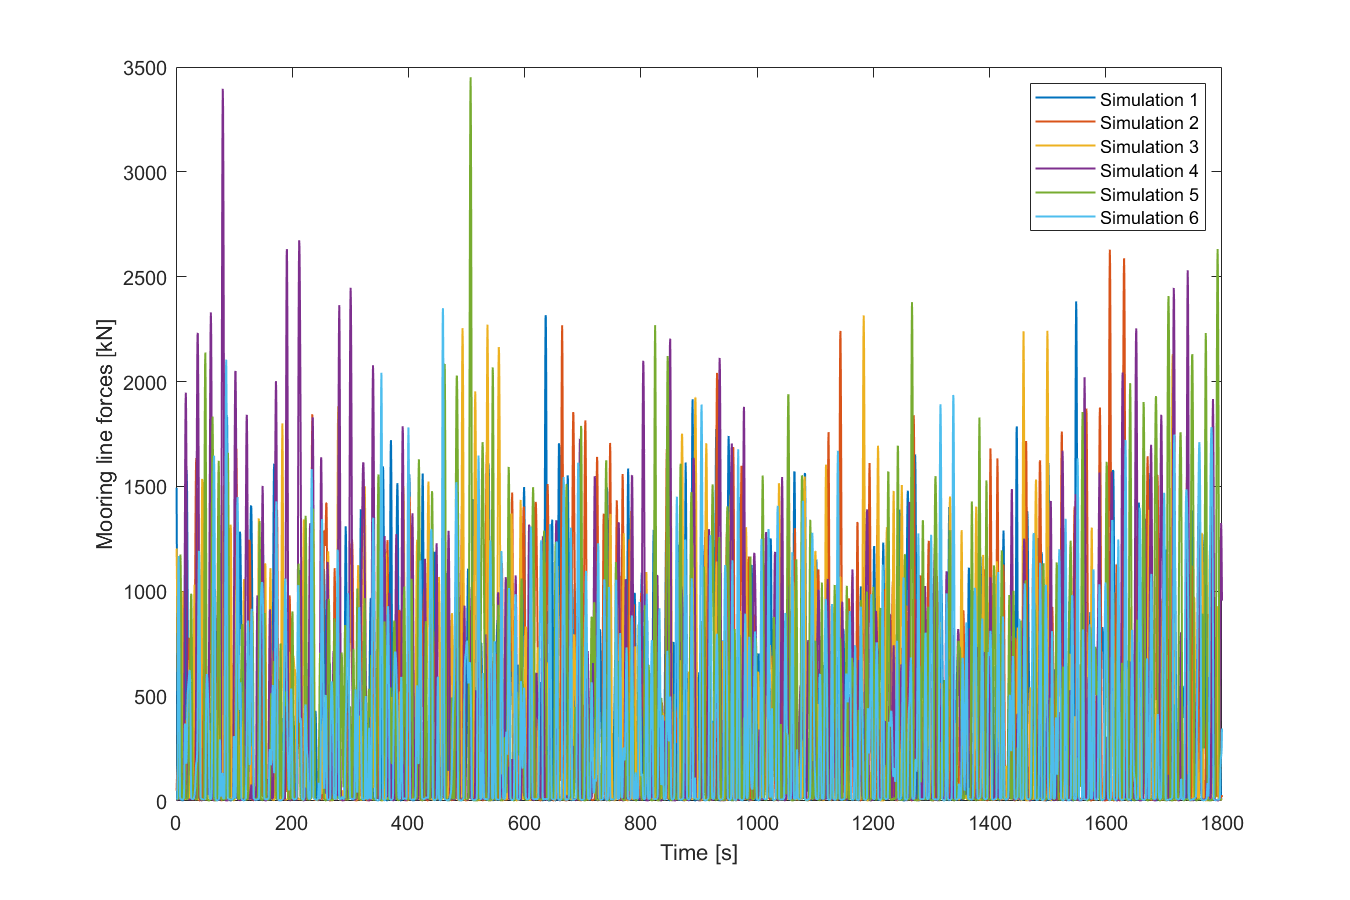

% Define the sheet name and line index
sheetName = '14';
lineIdx = 2;

% Read the sheet
data = readmatrix(filename, 'Sheet', sheetName);

% Remove the first 1200 rows
data = data(1201:end, :);

% Extract the line forces for the specified line
lineForces = data(:, (lineIdx-1)*6 + 1 : lineIdx*6);
lineForces = lineForces./1000;

% Plot the six time series of line forces
f16=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
time = 1:0.5:size(lineForces, 1)/2+0.5;
plot(time, lineForces(:, 1), 'LineWidth', 1);
hold on;
plot(time, lineForces(:, 2), 'LineWidth', 1);
plot(time, lineForces(:, 3)', 'LineWidth', 1);
plot(time, lineForces(:, 4), 'LineWidth', 1);
plot(time, lineForces(:, 5), 'LineWidth', 1);
plot(time, lineForces(:, 6), 'LineWidth', 1);
hold off;

% Add labels and title
xlabel('Time [s]');
ylabel('Mooring line forces [kN]');
xlim([0 1800])
legend('Simulation 1', 'Simulation 2', 'Simulation 3', 'Simulation 4', 'Simulation 5', 'Simulation 6');

exportgraphics(f16,'MooringTimes.pdf')